# Step 3: 系統データの見方と編集

系統モデル（`PowerNetwork`）から母線・ブランチ・機器・制御器を取り出し、そのパラメータと平衡点の値を読み書きする方法をまとめます。最後に、同じことを GUI で行う入口を紹介します。

この Step は、GUILDA の基本的な流れの赤枠の部分です。

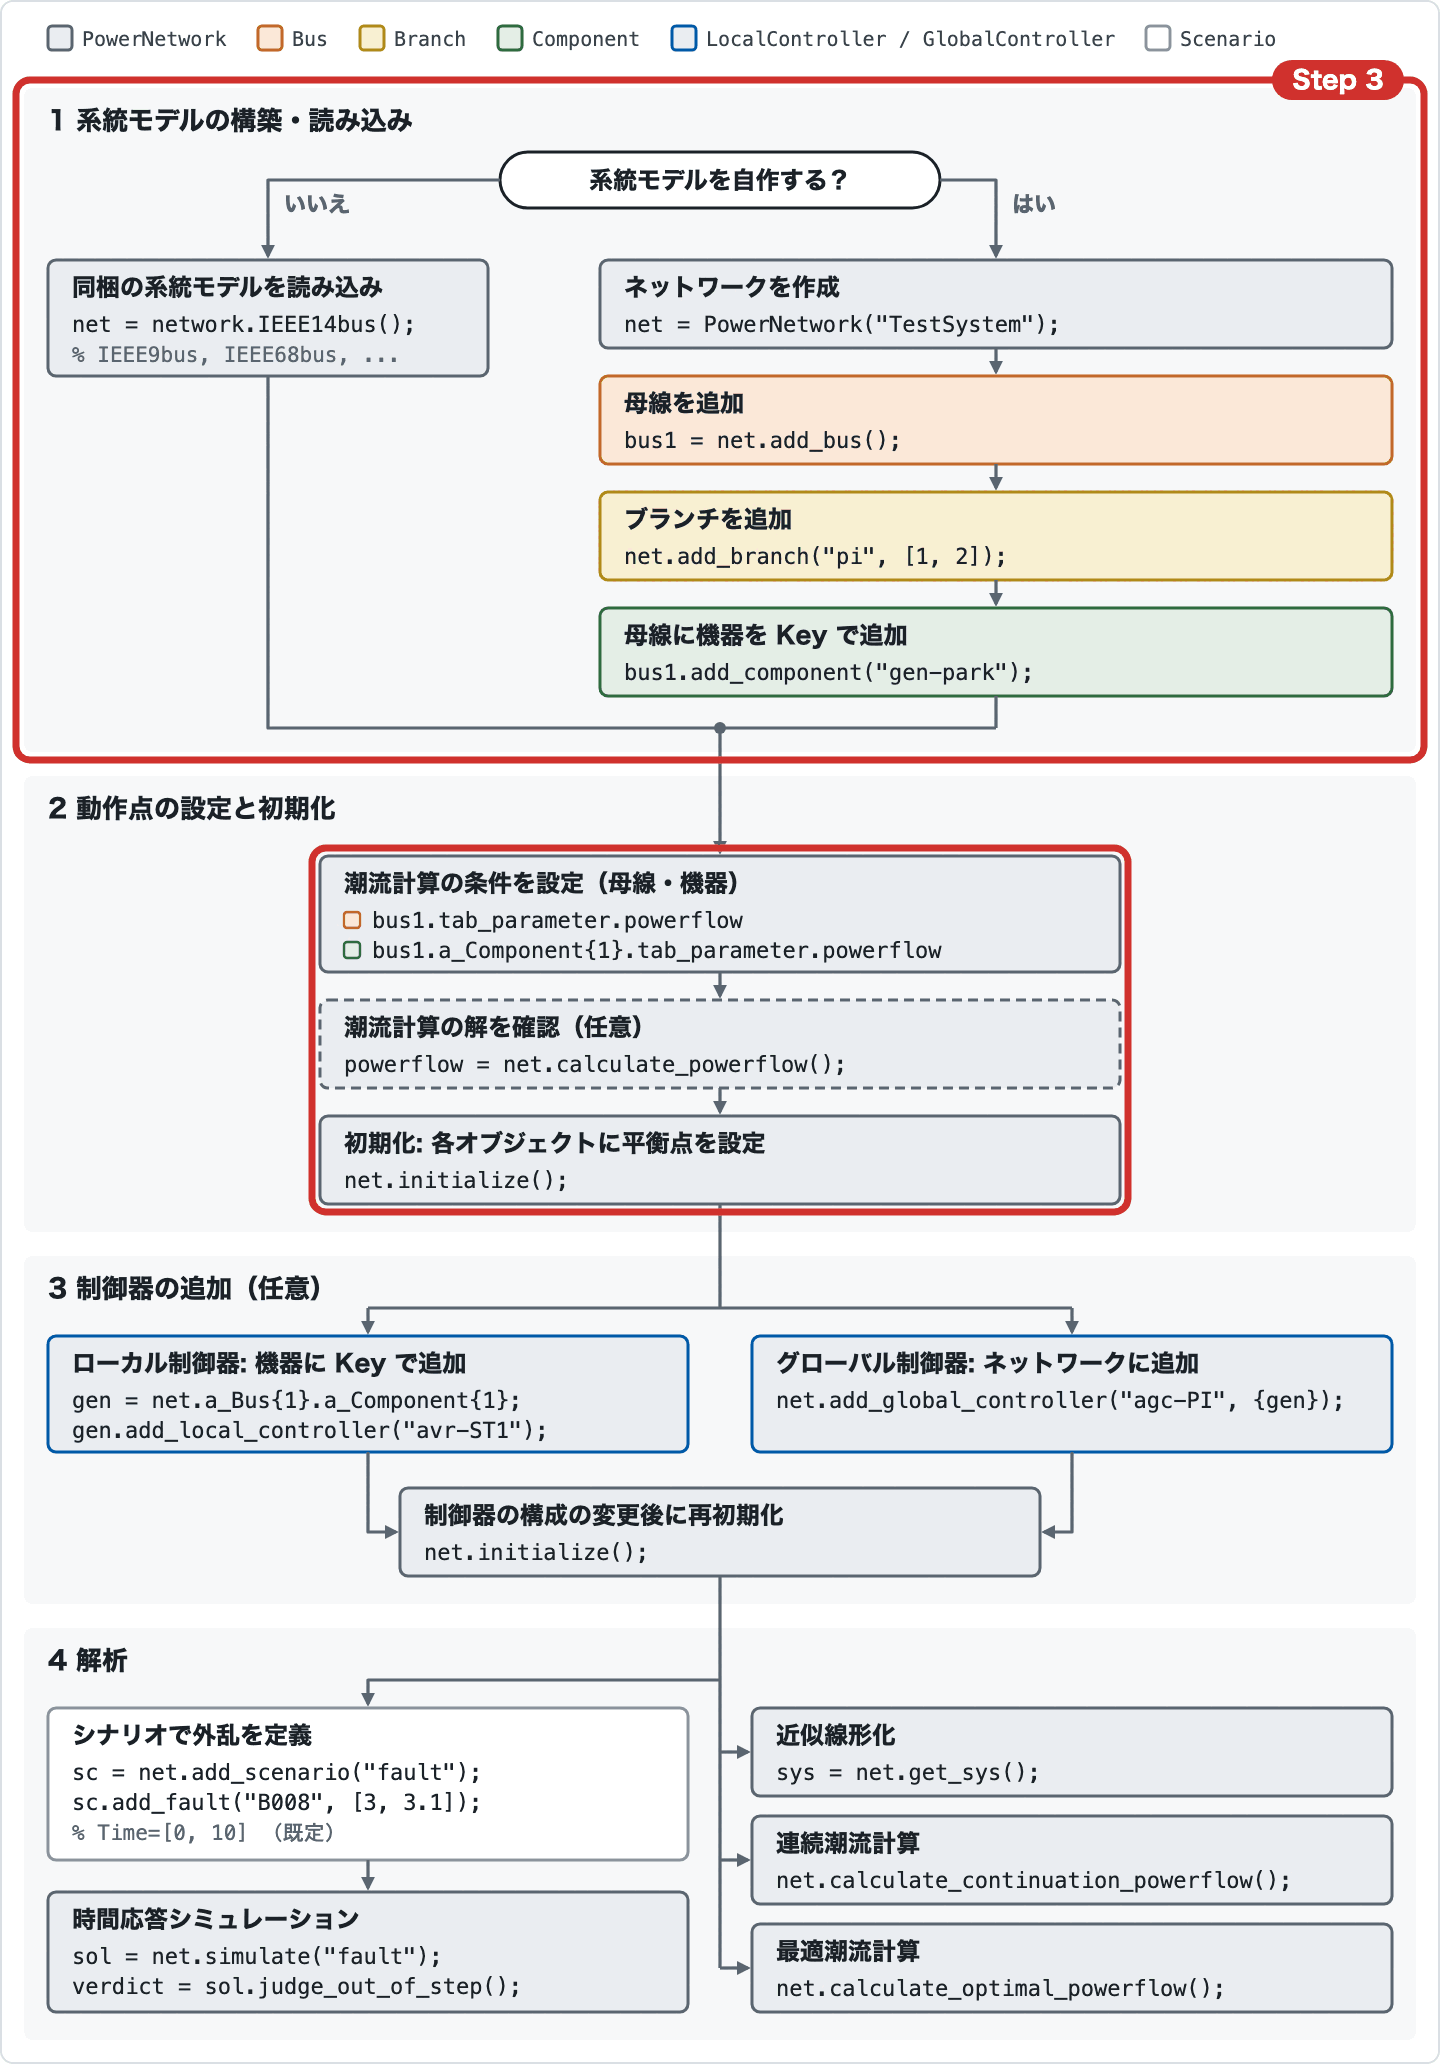

## この Step で分かること

- 母線・ブランチ・機器・制御器を、番号やタグで取り出す方法

- パラメータの表 `tab_parameter` の組み立てと、値の読み書きの方法（1 つの部品、まとめて多くの部品）

- 平衡点の値（電圧・状態・入力）の読み方と、変数の一覧 `get_variable_map`

- 系統のデータを表示する `disp_*`・`get_*_condition` の使い分け

- GUI（`launch_gui`・`GUILDA.launch_gui`）で系統を見て編集する方法

各節のコードは、その節の作業に要るものだけです。中身を表示して確かめるコードは「**確かめる（省略できます）**」の下に分けてあります。飛ばしても、最後まで実行できます。

**注意:** GUILDA を起動してから（`>> GUILDA`）実行してください。ここでは IEEE 9 母線系統を使います。

net = network.IEEE9bus(LocalController=true);

## 1. 部品を取り出す

系統モデルは、部品のオブジェクトを下の図のように入れ子で持ちます。母線は `a_Bus`、ブランチは `a_Branch`、グローバル制御器は `a_GlobalController` にあり、機器は母線の `a_Component`、ローカル制御器は機器の `a_LocalController` にあります。

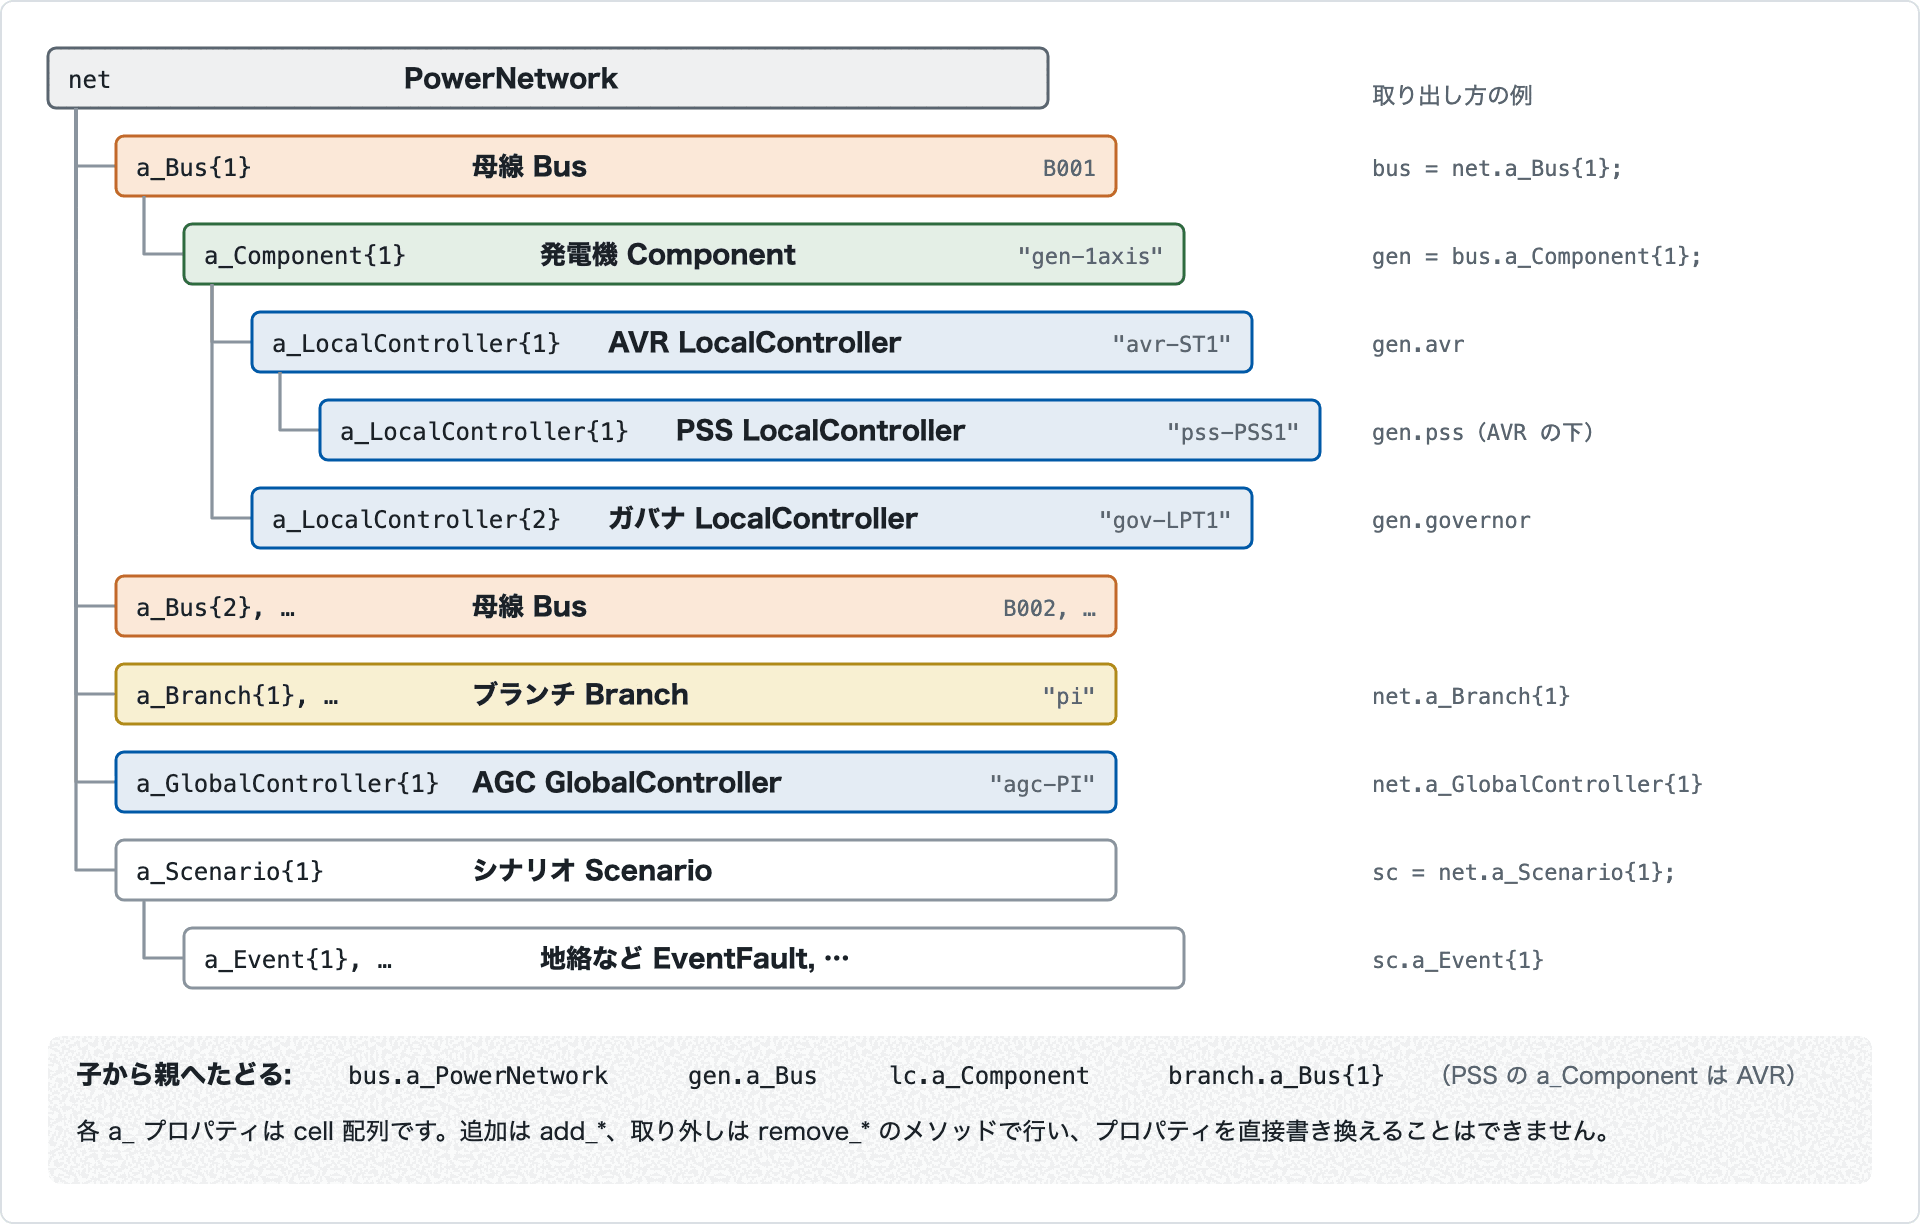

### 1.1 番号で取り出す

図のとおりに、cell 配列の番号で取り出します。PSS は AVR の `a_LocalController` にあります。

bus5 = net.a_Bus{5};
br1  = net.a_Branch{1};
gen1 = net.a_Bus{1}.a_Component{1};
avr1 = gen1.a_LocalController{1};
pss1 = avr1.a_LocalController{1};

**確かめる（省略できます）**

どの部品も、タグを `s_tag` に持ちます。取り出した部品のタグを並べます。

[bus5.s_tag, br1.s_tag, gen1.s_tag, avr1.s_tag, pss1.s_tag]

ans = 1×5 の string 配列
    "B005"    "ET001"    "B001SG1"    "B001SG1CA1"    "B001SG1CP2"


**注意:** 発電機の制御器は `gen1.avr`・`gen1.pss`・`gen1.governor` でも取り出せます（Step 2）。

### 1.2 タグで取り出す

`get_element` は、タグを指定して部品を取り出します。母線・ブランチ・機器・制御器のどれでも、どこにあっても同じ書き方です。

bus8 = net.get_element("B008");
ld8  = net.get_element("B008LRX1");

**確かめる（省略できます）**

[bus8.s_tag, ld8.s_tag, string(class(ld8))]

ans = 1×3 の string 配列
    "B008"    "B008LRX1"    "component.load.impedance"


タグを並べて渡すと、部品の cell 配列が返ります（例: `net.get_element(["B001","B001SG1CA1"])`）。

### 1.3 部品の一覧を見る

タグの一覧は `get_element_table` で見ます。`Kind` で部品の種類を選べます。機器の一覧を表示します。

net.get_element_table(Kind="component")

ans = 6×12 table
                   Tag           Kind              Key                       Class                 Role     Bus      Parent    From    To          State                Input             Output     
                __________    ___________    ________________    ______________________________    ____    ______    ______    ____    __    __________________    _______________    _______________

    B001SG1     "B001SG1"     "component"    "gen-1axis"         "component.generator.one_axis"     ""     "B001"    "B001"     ""     ""    "delta, omega, Eq"    "Pmech, Vfield"    "omega, Ifield"
    B002SG1     "B002SG1"     "component"    "gen-1axis"         "component.generator.one_axis"     ""     "B002"    "B002"     ""     ""    "delta, omega, Eq"    "Pmech, Vfield"    "omega, Ifield"
    B003SG1     "B003SG1"     "component"    "gen-1axis"         "component.generator.one_axis"     ""     "B003"    "B003"     ""     ""    "delta, omega, Eq"    "Pmech, Vfield"    "omega, 

表の `Key` がモデルを追加するときに使う Key（Step 1・2）、`Class` がモデルのクラス、`Bus` が機器のある母線、`State`・`Input`・`Output` が状態・入力・出力の名前です。ブランチの一覧（`Kind="branch"`）では、`From`・`To` の列に両端の母線が並びます。

`Kind` に指定できる種類と、下にある部品だけに絞る `Owner` などの、[その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=PowerNetwork&method=get_element_table')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）。

## 2. パラメータの表を読む

### 2.1 1 つの部品の表

部品のパラメータは、`tab_parameter` に表でまとまっています。表はグループごとの列に分かれています。

- `dynamics`: モデルの定数（発電機の慣性定数、送電線のインピーダンス、制御器のゲインなど）

- `powerflow`: 潮流計算の設定（母線の `V`・`Varg`、機器の `P`・`Q`）

- `operation`: 運転の上下限（電圧、送電容量、出力など）

- `OPF`: 最適潮流計算の費用と初期値（機器）

- `graph`: 系統図の描き方（位置・形・色）

系統の `tab_parameter` は `base`（`Hz` と `baseMVA`）だけです。母線と機器の表を見ます。

bus5.tab_parameter

ans = 1×4 table
        dynamics              operation           powerflow                             graph                         
    ________________    ______________________    _________    _______________________________________________________

    Gshunt    Bshunt    baseKV    Vmin    Vmax    V    Varg     X      Y      Shape      Length    MarkerSize    Color
    ______    ______    ______    ____    ____    _    ____    ___    ___    ________    ______    __________    _____
                                                                                                                      
      0         0        230      0.5     1.5     1     0      NaN    NaN    "square"     NaN         NaN         ""  


gen1.tab_parameter

ans = 1×5 table
                     dynamics                                     operation                   powerflow                                 OPF                                                              graph                             
    ___________________________________________    _______________________________________    __________    ____________________________________________________________    _______________________________________________________________

     M     D     Xd       Xq      Xd_p     Td_p    baseMVA    Pmin    Pmax    Qmin    Qmax     P      Q     P0    Q0    HP    HQ    fP    fQ    c    startup    shutdown    DX     DY      Shape      Path    Offset    MarkerSize    Color
    ___    _    _____    _____    _____    ____    _______    ____    ____    ____    ____    ___    ___    __    __    __    __    __    __    _    _______    ________    ___    ___    ________    ____    ______    __________    _____
                                       

グループを指定すると、その表だけを取り出せます。値は表の列名で読みます。

gen1.tab_parameter.dynamics

ans = 1×6 table
     M     D     Xd       Xq      Xd_p     Td_p
    ___    _    _____    _____    _____    ____

    100    2    1.569    1.548    0.324    5.14


M1 = gen1.tab_parameter.dynamics.M

M1 = 100

制御器の表は `dynamics` だけです。

avr1.tab_parameter.dynamics

ans = 1×11 table
    ttr    Vap_max    Vap_min    kap    tap     kst    tst    Limiter    gamma_max    gamma_min    k0
    ___    _______    _______    ___    ____    ___    ___    _______    _________    _________    __

     0       Inf       -Inf       2     0.05     0      0      true         Inf         -Inf       0 


### 2.2 多くの部品の表をまとめて読む

`get_parameter` は、1 つのグループを、部品ごとに 1 行の表にまとめて返します。`Key`・`Class`・`Owner` で部品を選びます。3 台の発電機の定数と、母線の潮流の設定を並べます。

net.get_parameter("dynamics", Key="gen-1axis")

ans = 3×6 table
                M     D     Xd       Xq      Xd_p     Td_p
               ___    _    _____    _____    _____    ____

    B001SG1    100    2    1.569    1.548    0.324    5.14
    B002SG1     18    2    1.651     1.59    0.232     5.9
    B003SG1     12    2     1.22     1.16    0.174    8.97


net.get_parameter("powerflow", Class="Bus")

ans = 9×2 table
              V      Varg
            _____    ____

    B001     1.04     0  
    B002    1.025     0  
    B003    1.025     0  
    B004        1     0  
    B005        1     0  
    B006        1     0  
    B007        1     0  
    B008        1     0  
    B009        1     0  


行の名前が部品のタグです。モデルが違うと列が違うので、`dynamics` は `Key` か `Class` で 1 つのモデルに絞ります（違うモデルが混ざると、モデルごとの列を示すエラーになります）。`Class="component.load.abstract"` のように親クラスを指定すると、そのクラスを継承するすべてのモデル（ここではすべての負荷）を選べます（3.3 で使います）。

**注意:** パラメータの意味と単位は、クラスの説明（`help component.generator.one_axis` や `gen1.doc()`）にあります。

## 3. パラメータを書き換える

### 3.1 1 つの値を書き換える

`tab_parameter` に、グループと列名を指定して書き込みます。母線 1 の発電機の慣性定数を変えます。

gen1.tab_parameter.dynamics.M = 30;

母線・ブランチ・制御器も同じように書き換えられます（例: `bus5.tab_parameter.operation.Vmin = 0.95;`、`avr1.tab_parameter.dynamics.kap = 40;`）。

**確かめる（省略できます）**

gen1.tab_parameter.dynamics.M

ans = 30

### 3.2 1 つの部品のグループの表をまとめて書き換える

表を取り出して変え、まとめて書き戻すこともできます。1 つの部品の複数の値を一度に変えるときに便利です。

tp = br1.tab_parameter.dynamics;
tp.X = 1.1*tp.X;
tp.tap = 0.98;
br1.tab_parameter.dynamics = tp;

書き戻す表は、もとの表と同じ列（順序は問いません）・行数・行名でなければなりません。違うとエラーになり、何も変わりません。値の型が違う場合もエラーになります。

**確かめる（省略できます）**

書き戻した表を表示します。続けて、列を足した表と、型の違う値を書き込んで、エラーの文を表示します（どちらも何も変わりません）。

br1.tab_parameter.dynamics

ans = 1×6 table
    R       X       C    tap     phase    circuit
    _    _______    _    ____    _____    _______

    0    0.06336    0    0.98      0         2   


try
    tp_bad = tp;
    tp_bad.X2 = 0.1;
    br1.tab_parameter.dynamics = tp_bad;
catch ME
    disp(ME.message)
end

The dynamics table must keep its parameters (R, X, C, tap, phase, circuit), its height (1) and its row names. Nothing was changed.


try
    gen1.tab_parameter.dynamics.M = "large";
catch ME
    disp(ME.message)
end

'M' must be double, but a value of class string was given. The value was not changed.


### 3.3 多くの部品の値をまとめて書き換える

`get_parameter` で読んだ表を変えて `set_parameter` で書き戻すと、多くの部品の値を一度に書き換えられます。すべての負荷を 1.2 倍にします。

tab_load = net.get_parameter("powerflow", Class="component.load.abstract");
tab_load.P = 1.2*tab_load.P;
tab_load.Q = 1.2*tab_load.Q;
net.set_parameter("powerflow", tab_load);

書き戻す表は、一部の行や列だけでもかまいません（例: `net.set_parameter("dynamics", tab("B002SG1", "D"))`）。行の名前のタグがない、列の名前のパラメータがない、型が違う、といった行が 1 つでもあると、エラーになり何も書き込みません。

**確かめる（省略できます）**

net.get_parameter("powerflow", Class="component.load.abstract")

ans = 3×2 table
                  P        Q  
                _____    _____

    B005LRX1     -1.5     -0.6
    B006LRX1    -1.08    -0.36
    B008LRX1     -1.2    -0.42


### 3.4 書き換えた後に平衡点を求め直す

パラメータを書き換えると、平衡点は古くなります。`initialize` で求め直すと、新しいパラメータの値が平衡点に表れます。

[~, flag] = net.initialize();

**注意:** `initialize` の前は、平衡点のプロパティ（`c_Vequilibrium` など）は書き換える前の値のままです。どの部品が古くなっているかは、`disp_summary` の一覧の `Equilibrium` の行や、GUI（6 節）の Stale の欄で確かめられます。系統の `tab_parameter.base` の `Hz`・`baseMVA` も同じように書き換えられます。

**確かめる（省略できます）**

負荷のある母線 8 の電圧を、書き換えていない系統と比べます。3 つ目の値は `initialize` が成功したかどうか（`flag`）です。

net_ref = network.IEEE9bus(LocalController=true);
[abs(net_ref.get_element("B008").c_Vequilibrium), abs(bus8.c_Vequilibrium), flag]

ans =     1.0159    1.0081    1.0000


負荷が増えたので、母線 8 の電圧が下がりました。

## 4. 平衡点の値を読む

### 4.1 電圧と電力

`initialize` で求めた平衡点は、部品ごとのプロパティで読めます。

- 系統: `cv_Vequilibrium`・`cv_Iequilibrium`（母線ごとの電圧と電流のフェーザ）

- 母線: `c_Vequilibrium`・`c_Iequilibrium`

- 機器: `rv_Xequilibrium`（状態）・`rv_Uequilibrium`（入力）・`c_Iequilibrium`（機器が送り込む電流）

- 制御器: `rv_Xequilibrium`・`rv_Uequilibrium`

母線ごとの電圧の大きさと位相、母線から系統へ送り込む電力は、`disp_powerflow` でまとめて表示できます。

net.disp_powerflow();


  Steady-State PowerFlow

            theta(°)    theta(rad)    |V|(pu)    P(pu)       Q(pu)  
            ________    __________    _______    ______    _________

    B001           0            0        1.04    1.3486      0.52346
    B002      4.5815     0.079963       1.025      1.63      0.12672
    B003     0.10112    0.0017648       1.025      0.85    -0.059976
    B004     -4.4699    -0.078014      1.0331         0            0
    B005     -7.8369     -0.13678     0.99199      -1.5         -0.6
    B006     -7.3047     -0.12749      1.0111     -1.08        -0.36
    B007    -0.99871    -0.017431      1.0221         0            0
    B008     -4.4003    -0.076799      1.0081      -1.2        -0.42
    B009     -2.6042    -0.045452      1.0296         0            0



3.3 で負荷を増やしたので、負荷のある母線 5・6・8 の `P`・`Q` が、もとの値の 1.2 倍になっています。

### 4.2 状態と入力：変数の一覧

`get_variable_map` は、変数（状態 `x`、母線の電圧 `Vre`・`Vim`、入力 `u`・`uc`、出力 `y`・`yc`）を 1 行ずつ並べた表を返します。`Equilibrium` の列が平衡点の値です。機器の `get_variable_map` は、その機器と制御器の行、つながる母線の電圧の行を返します。母線 1 の発電機と、その AVR・PSS・ガバナの変数を見ます。

tab_var = gen1.get_variable_map();
tab_var(:, ["Kind","Owner","Name","Label","Equilibrium"])

ans = 23×5 table
    Kind        Owner          Name             Label           Equilibrium
    _____    ____________    ________    ___________________    ___________

    "x"      "B001SG1"       "delta"     "delta_B001SG1"          0.83453  
    "x"      "B001SG1"       "omega"     "omega_B001SG1"                0  
    "x"      "B001SG1"       "Eq"        "Eq_B001SG1"              1.1192  
    "x"      "B001SG1CA1"    "Vtr"       "Vtr_B001SG1CA1"            1.04  
    "x"      "B001SG1CA1"    "Vap"       "Vap_B001SG1CA1"          2.7362  
    "x"      "B001SG1CA1"    "Vst"       "Vst_B001SG1CA1"               0  
    "x"      "B001SG1CP2"    "xiWS"      "xiWS_B001SG1CP2"              0  
    "x"      "B001SG1CP2"    "xi1"       "xi1_B001SG1CP2"               0  
    "x"      "B001SG1CP2"    "xi2"       "xi2_B001SG1CP2"               0  
    "Vre"    "B001"          "Vre"       "Vre_B001"                  1.04  
    "Vim"    "B001"          "Vim"       "Vim_B001"                   

`Label` は、時間シミュレーションの結果や近似線形モデルで変数を指す名前です。系統の `net.get_variable_map()` はすべての変数を返し、行の順序がシミュレーションや線形化で使う変数の並びです。

**注意:** 機器の `rv_Xequilibrium_all` は、機器とそのローカル制御器の状態をまとめた平衡点です。`get_variable_map` の 4 番目の出力は、どの信号がどの入力を動かすかを表す接続の表です（`disp_connection` と同じ内容。Step 2）。

## 5. データを表示する

ここまでの作業に、表示は要りません。目的に合わせて、次の表示を使い分けます。

- `disp_tree`: 部品の階層（Step 1）

- `disp_summary`: 系統が持つものの一覧と、母線・ブランチ・機器の表（パラメータと平衡点）

- `disp_powerflow`: 平衡点の母線の電圧と電力（4.1）

- `get_element_table`: 部品の一覧（1.3）

- `get_pf_condition`: 潮流計算に使う母線の条件（種類と設定値）

- `get_opf_condition`: 最適潮流計算に使う条件（母線・機器・ブランチの上下限と費用）

- `disp_connection`: 信号のつながり（Step 2）

- `get_admittance_matrix`: 母線のアドミタンス行列

**確かめる（省略できます）**

`disp_summary` で、系統が持つものの一覧と、機器の表だけを表示します。

net.disp_summary(bus=false, branch=false, parameter=false);

PowerNetwork (network.IEEE9bus): 60 Hz, base 100 MVA
- Buses: 9 (slack 1, PV 2, PQ 6); slack bus: B001
- Branches: 9
    - pi_transformer: 3 (ET001, ET002, ET003)
    - pi: 6 (EL004, EL005, EL006, EL007, EL008, EL009)
- Components: 6
    - gen-1axis: 3 (B001SG1, B002SG1, B003SG1)
    - load-impedance: 3 (B005LRX1, B006LRX1, B008LRX1)
- Local controllers: 9 (avr 3, pss 3, governor 3)
    - avr-ST1: 3 (B001SG1CA1, B002SG1CA1, B003SG1CA1)
    - pss-PSS1: 3 (B001SG1CP2, B002SG1CP2, B003SG1CP2)
    - gov-static: 3 (B001SG1CG1, B002SG1CG1, B003SG1CG1)
- Global controllers: none
- Scenarios: none
- Equilibrium: up to date

Components: gen-1axis (component.generator.one_axis)
       Tag        Bus                  Controller                               Equilibrium               
    _________    ______    __________________________________    _________________________________________

                                                                   V        theta        P           Q    
 

一覧には、母線の種類ごとの数、モデルの Key ごとの部品の数とタグ、平衡点が最新かどうかが並びます。最適潮流計算の条件を表示します（最適潮流計算は Step 9 で扱います）。

net.get_opf_condition();

Bus
            Vmin    Vmax    Gshunt    Bshunt     Type        V      Varg
            ____    ____    ______    ______    _______    _____    ____

    B001    0.5     1.5       0         0       "slack"     1.04     0  
    B002    0.5     1.5       0         0       "PV"       1.025     0  
    B003    0.5     1.5       0         0       "PV"       1.025     0  
    B004    0.5     1.5       0         0       "PQ"           1     0  
    B005    0.5     1.5       0         0       "PQ"           1     0  
    B006    0.5     1.5       0         0       "PQ"           1     0  
    B007    0.5     1.5       0         0       "PQ"           1     0  
    B008    0.5     1.5       0         0       "PQ"           1     0  
    B009    0.5     1.5       0         0       "PQ"           1     0  

Component
                 Bus      HP    fP    HQ    fQ    c     P0       Q0      Pmin     Pmax     Qmin     Qmax 
                ______    __    __    __    __    _    _____    _____    __

アドミタンス行列は、行と列が母線のタグの表で返ります。

Y = net.get_admittance_matrix();
Y(1:4, 1:4)

ans = 4×4 table
              B001       B002       B003            B004     
            _________    _____    _________    ______________

    B001    0-16.434i    0+0i     0+0i              0+16.105i
    B002    0+0i         0-16i    0+0i              0+0i     
    B003    0+0i         0+0i     0-17.065i         0+0i     
    B004    0+16.105i    0+0i     0+0i         3.3074-37.731i


`get_pf_condition` と `get_opf_condition` は母線・ブランチ・機器からも使えます（例: `bus5.get_pf_condition()`）。`disp_summary` の表示する表を選ぶオプションなど、その他のオプションは[こちら（disp_summary）](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=PowerNetwork&method=disp_summary')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))・[こちら（get_pf_condition）](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=PowerNetwork&method=get_pf_condition')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）。`doc` は、部品のクラスの説明のページを開きます（例: `gen1.doc()`）。

## 6. GUI で見て編集する

同じことは GUI でもできます。次のコマンドを実行すると、GUI が起動します（このライブスクリプトでは実行しません。コマンドウィンドウに入力してください）。

- `net.launch_gui()`: モデルの GUI。部品からも開けます（例: `net.a_Bus{1}.launch_gui()`）。

- `GUILDA.launch_gui(net)`: 系統図と解析のタブを持つ GUILDA アプリ。系統を渡さないと、系統を選ぶ画面から始まります。

### 6.1 モデルの GUI

部品の一覧から子の部品へたどり、パラメータの表を直接書き換えられます。`+ Bus` などのボタンで部品を加え、一覧のメニューで取り除けます。上の帯に、開いているモデルとクラス、`Docs`（クラスの説明）、`Stale`（平衡点が古くなっている部品）が並びます。左が子の部品の一覧で、右のタブにパラメータ（Parameter）、表（Summary）、平衡点（Equilibrium）が並びます。

**注意:** GUI での操作は、同じ意味の MATLAB のコードとしてコマンドウィンドウに表示され、記録されます（`h = net.launch_gui();` と出力を受け取ると、`h.history.get_script()` でスクリプトとして取り出せます）。

### 6.2 GUILDA アプリ

上のタブで画面を切り替えます。タブは Model（系統モデルの作成）、Power flow（潮流計算）、OPF（最適潮流計算）、CPF（連続潮流計算）、Time simulation（時間シミュレーション）、Linearization（近似線形化）です。どのタブでも、左に系統図と操作の記録（Log）が並びます。Model のタブでは右にモデルの GUI が並び、系統図の母線・ブランチ・機器をクリックすると、右にその部品が開きます。系統図の描き方は `Display options` ボタンで変えられます。

**注意:** `Export script` ボタンで、アプリでの操作をスクリプトとして書き出せます。系統を選ぶ画面からは、空の系統、同梱の系統、保存したフォルダ、MATPOWER のケースを開けます。

## まとめ

- 部品は `a_Bus`・`a_Branch`・`a_Component`・`a_LocalController`・`a_GlobalController` から番号で、`get_element` でタグで取り出します。一覧は `get_element_table` で見ます。

- パラメータは `tab_parameter` の表（`dynamics`・`powerflow`・`operation`・`OPF`・`graph`）で読み書きします。多くの部品をまとめて扱うときは `get_parameter`・`set_parameter` を使います。

- 書き換えた後は `initialize` で平衡点を求め直し、平衡点は `disp_powerflow`、`*equilibrium` のプロパティ、`get_variable_map` で読みます。

- 表示は `disp_summary`・`disp_powerflow`・`get_element_table`・`get_pf_condition`・`get_opf_condition`・`disp_connection`・`get_admittance_matrix` を使い分けます。どれも必須ではありません。

- GUI は `obj.launch_gui()`（モデルの GUI）と `GUILDA.launch_gui(net)`（アプリ）で開きます。

## 次の Step と関係する Part

- 次の Step 4（潮流計算）では、潮流計算の実行と結果の見方を扱います。

- 系統の部品とパラメータの考え方は Part 1（電力系統の作成と機器の種類）で、潮流計算の考え方は Part 2（潮流計算）で説明しています: [講義ノート Part 1](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part1-network-components.html","-browser"))・[講義ノート Part 2](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part2-power-flow.html","-browser"))（ブラウザで開きます）

[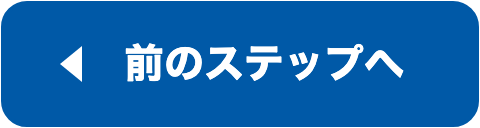](matlab:open('Step2_ComponentController.mlx'))　　[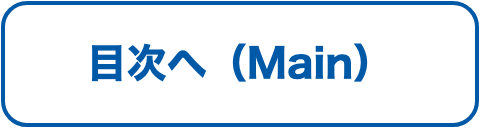](matlab:open('Main.mlx'))　　[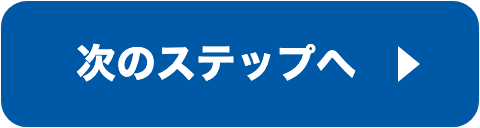](matlab:open('Step4_PowerFlow.mlx'))